clear all
close all

Simulating a Receiver with a Limited Bandwidth

Reduced bandwidth $f_{c}=\frac{B}{2}$

Butterworth: Filter second order, cutoff frequency @ $0.5 G$ Hz

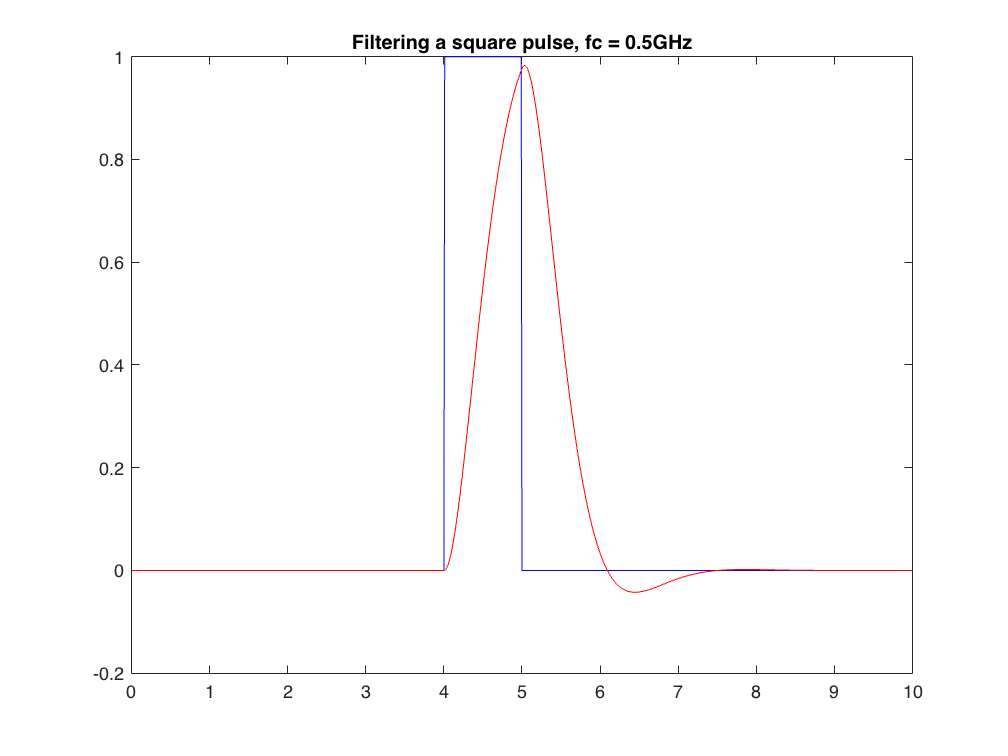

n = 1000;
tstep = 1/100;  % ns
tbin = 10 / n;                   % The width of time bins (in nsec)
t = linspace(0, 10, n+1);       % A set of time points
fs = 1/tstep;                  % The sampling frequency
sig = 1 .* (t>4) .* (t<5);
figure(1);
plot(t, sig, 'b');           % Plot the input signal
hold on
fc = 0.5; %GHz  

[b,a] = butter(2,fc/(fs/2));

dataIn = sig;
dataOut = filter(b,a,dataIn);

plot(t, dataOut, 'r'); 

title('Filtering a square pulse, fc = 0.5GHz')


$$E = hv = \frac{hc}{\lambda}$$


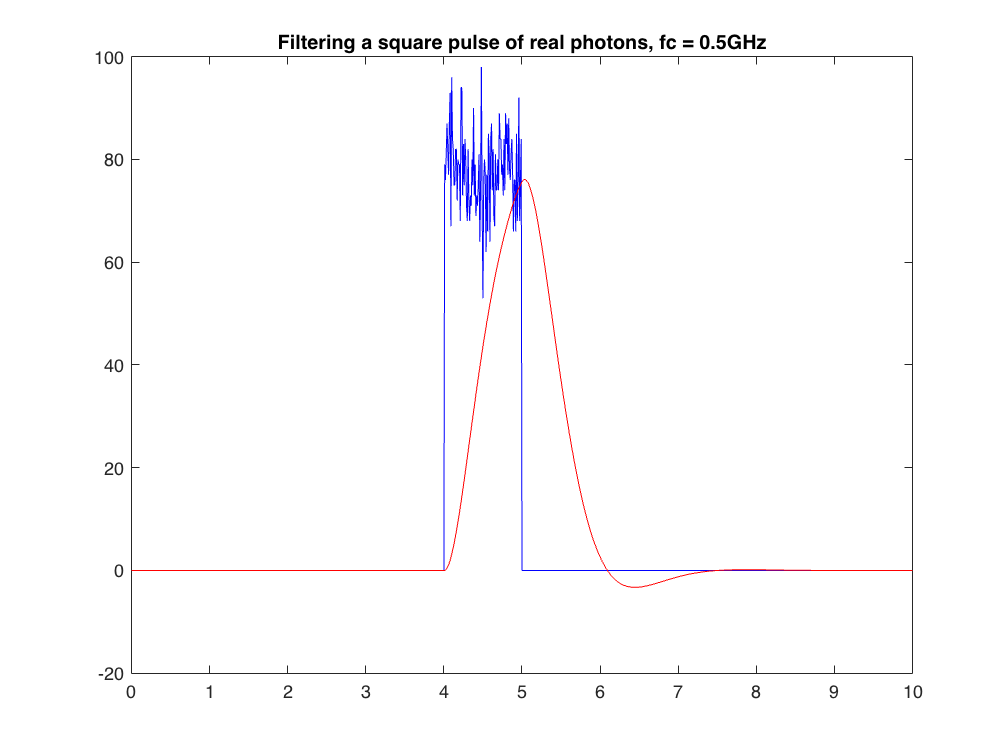

signal_power = 1e6;    %pw
wavelwngth = 1.55e-6; %um

figure(2)
Uphoton = physconst('LightSpeed')*6.62607015*10^(-34)/wavelwngth * 10^12; %pj
sig_photon_e = signal_power * tstep * 1e-9 / Uphoton .* sig;
sig_photon = poissrnd(sig_photon_e);
sig_photon_filt = filter(b,a,sig_photon);
plot(t,sig_photon,'b');
hold on 
plot(t,sig_photon_filt,'r')
title('Filtering a square pulse of real photons, fc = 0.5GHz')


$$B_{s} = \frac{f_{s}}{2}$$


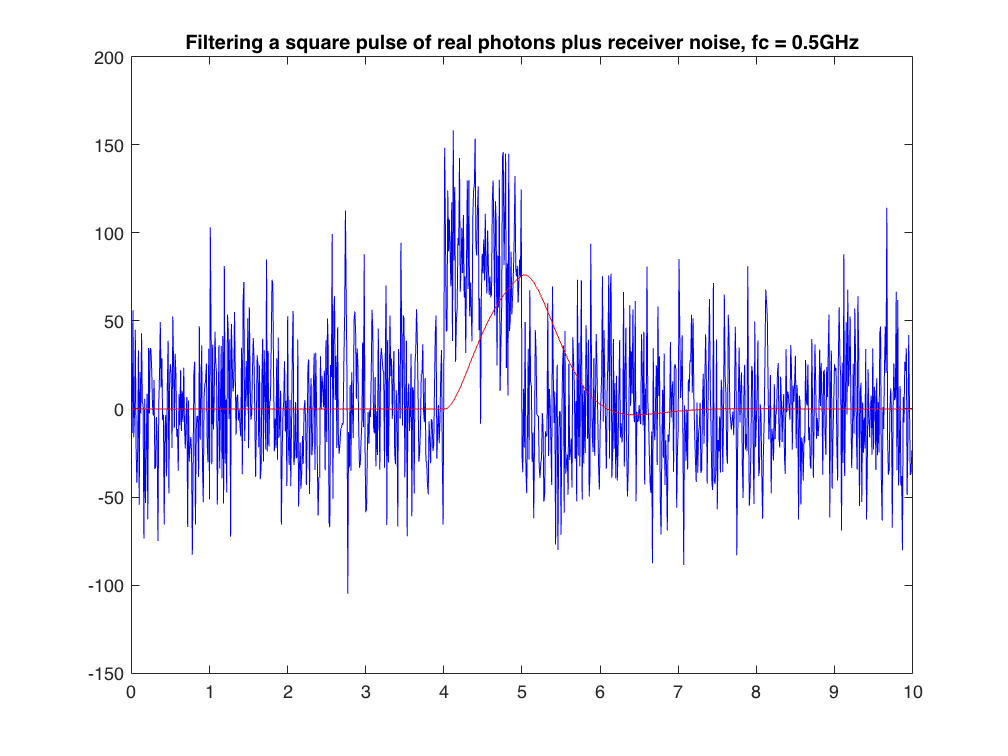

NEP = 2; %Units are pW/sqrt(Hz)
Pnoise = NEP * (fs/2*1e9)^0.5; %calculate noise power (RMS) in pW for sampling frequency fs

Nnoise_rms = Pnoise * tstep * 1e-9 / Uphoton;
Nnoise = normrnd(0,Nnoise_rms,[1,n+1]);

figure(3)
plot(t, Nnoise + sig_photon, 'b')
hold on
sig_filt = filter(b,a,sig_photon);
plot(t,sig_filt,'r')
title('Filtering a square pulse of real photons plus receiver noise, fc = 0.5GHz')

Eye-diagram generation

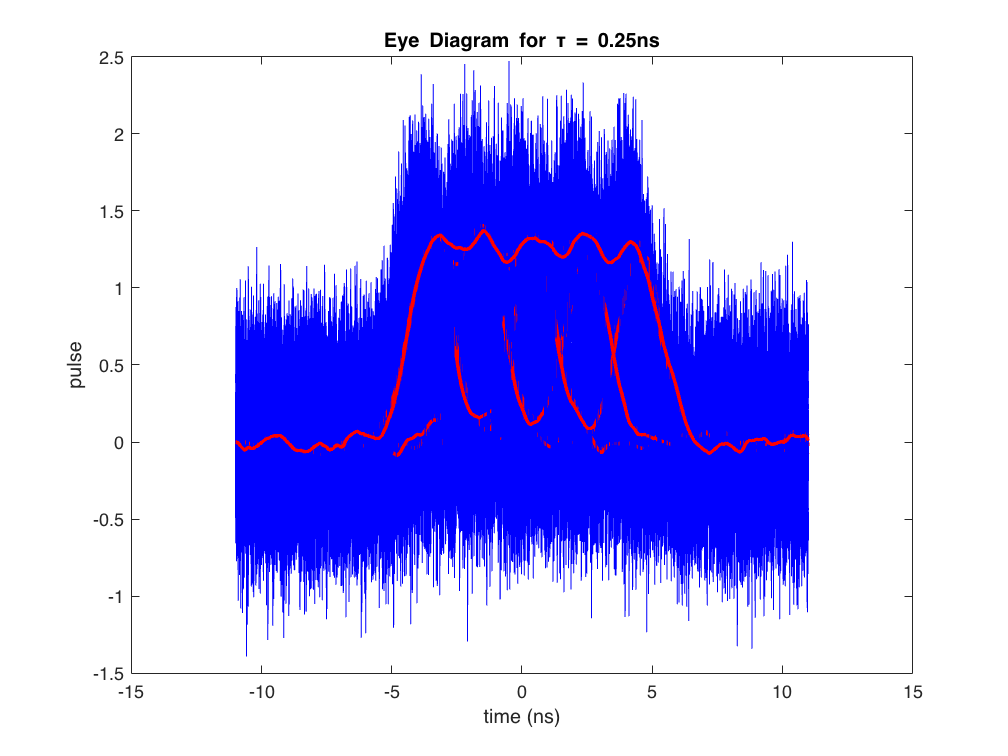

D = 15; %15ps/nm/km
delta_lambda = 0.1; %nm
tau_0 = [0.8]; %ns
L = 0; %km
delta_tau = D*delta_lambda*L/1000; %ns
tau = (tau_0.^2 + delta_tau^2).^0.5; % pulse width considering dispersion
bitnumber = 5;
interval = 2; % ns
range = (bitnumber+6) * interval; %ns
resolution = 0.01;
P_0 =1;
t = -range/2:resolution:range/2;

NEP = 0.02; %Units are pW/sqrt(Hz)
Pnoise = NEP * (fs/2*1e9)^0.5; %calculate noise power (RMS) in pW for sampling frequency fs

Nnoise_rms = Pnoise * tstep * 1e-9 / Uphoton;

for i=1:2^bitnumber
    i = i - 1;
    sequence = dec2binarr(i,bitnumber);
    Nnoise = normrnd(0,Nnoise_rms,[1,length(t)]);
    P_025 = Nnoise;

    for ii = 1:bitnumber
        if sequence(ii)==1    
            P_temp = P_0/tau(1) * exp(-(t+range/2-ii*interval-2.5*interval).^2/2/tau(1)^2);
            P_025 = P_temp + P_025;
        end
    end

    figure(4)
    plot(t,P_025,'b')
    hold on
    title('Eye Diagram for \tau = 0.25ns')
    xlabel('time (ns)') 
    ylabel('pulse') 

    sig_filt = filter(b,a,P_025);
    plot(t,sig_filt,'r',LineWidth = 2)




end